clc
clear
close all

## Load CasADi

addpath('C:\dev\casadi-windows-matlabR2016a-v3.5.2')
import casadi.*

## Define symbolic variables

x = SX.sym('x',4);
u = SX.sym('u');
cA=x(1);
cB=x(2);
T=x(3);
xk = [2274;7726;444;0];     %initial value

timeEnd = 20;               %final time
N = 1000;
dt = timeEnd/N;             %step size
ts = 0:dt:timeEnd;

## I. Data (parameters and independent variables)

All in SI units except time which is in minutes.

cAf=10000;             % feed concentration of A [mol/m3]
cBf=0;                 % feed concentration of B [mol/m3]
Tf=300;                % feed temperature [K]
V = 0.9;               % reactor volume [m3]
q = 0.12;              % volumetric flowrate [m3/min] (KAN ENDRES)
dhr=  -80e3;           % Heat of reaction [J/mol]
cp= 4.e3;              % heat capacity [J/kg]
rho = 1000;            % mean density [kg/m3]
U = 1000*60;           % heat transfer coefficient [J/min,m2,K]
A = 5;                 % heat transfer area [m2]
k1_400 = 0.1;          % rx1: rate constant at 400K [1/min]
k2_400 = 0.001;        % rx2: rate constant at 400K [1/min]
E1 = 60e3;             % rx1: activation energy [J/mol]
E2 = E1 - dhr;         % rx2: activation energy
R = 8.31;              % [J/K mol]

% Tc = 430;              % cooling temperature [K]

## PI controller

yreg=T; %CV
yregs=444; %setpoint of CV
e=yreg-yregs;
eint=x(4); %deint/dt = e

u0=430; %initial value of MV
Kc=4.7; taui=7;%SIMC PI tuning
u = u0 - Kc*e - (Kc/taui)*eint;
Tc = u; %MV

## IIIa. Intermediate calculations

k1 = k1_400 * exp(-(E1/R) * (1/T - 1/400));
k2 = k2_400 * exp(-(E2/R) * (1/T - 1/400));
r = k1*cA - k2*cB;
Q = U*A*(Tc-T);

## IIIb. Evaluate derivatives of states

Vdcadt = q*cAf - q*cA - r*V;                   % [mol A/min]
Vdcbdt = q*cBf - q*cB + r*V;                   % [mol B/min]
mcpdTdt = rho*q*cp*(Tf-T) + r*V*(-dhr) + Q;    % [J/min]

f1 = Vdcadt/V;
f2 = Vdcbdt/V;
f3 = mcpdTdt / (rho*cp*V);

xdot=[f1; f2; f3; e];

## Formulate the dynamics

ode = struct('x',x,'ode',xdot);

## Building integrator

opts = struct('tf',dt);         %integrating from 0 - dt
F = integrator('F', 'cvodes', ode, opts);

x_n = xk;
for i = 1:(length(ts)-1)
    % Integrate till the end of the interval
    Fk = F('x0',xk);
    xk = full(Fk.xf);
    x_n = [x_n; full(Fk.xf)];
end
T = x_n(3:4:end);
eint = x_n(4:4:end);
for i=1:(length(ts))
    inp(i) = u0 - Kc*(T(i)-444) - (Kc/taui)*eint(i);
end

## Plotting

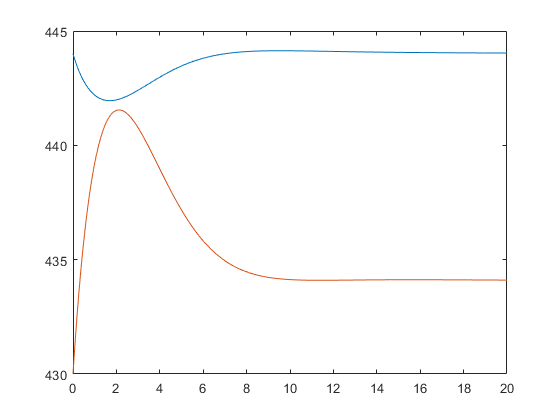

hold on;
plot(ts,T);plot(ts,inp)

xlabel('Time [min]'); ylabel('Temperature [K]')
hold off